# Amplitude vs. Rms

© 10 Feb 24 B. Rasnow

## Objective

Understand the differences between amplitude and rms measures of electronic signals. 

## Background

By Fourier's Theorem, any signal can be characterised by (linear) superposition of sinusoidal components, $A_\omega \cos(\omega t + \phi) = A_\omega Re[e^{i(\omega t +\phi)} ] = A_\omega Re[e^{i\omega t}e^{i\phi} ] = 
Re[ (A_\omega e^{i\phi}) e^{i\omega t} ] = Re[ A(\omega)  e^{i\omega t} ] $ where $A$ is generally complex, i.e., it contains the phase $\phi(\omega)$ within it. 

You've faithfully learned that the root mean square (rms) measure of such a signal component,$V_{RMS} = | A |/\sqrt{2} $. That's true for single frequency, but is it also true for a superposition? Does linearity apply, i.e., if you substitute $A+B$ for $A$, then $V_{RMS}(A+B) = \sqrt(2)| A+B |$and by linearity should equal  $V_{RMS}(A) + V_{RMS}(B) = (\sqrt{2} | A |) + (\sqrt{2} | B |) = \sqrt(2)(| A| + | B|)$. Houston, we have a problem ... in general, $|A + B| \ne |A| + | B|%$$. In fact, when *is* this true? \pause 

So the relationship between amplutide $A$ and $V_{RMS}(A)$ won't be so simple for superpositions of sinusoidal signals. 

Let's start exploring using numerical simulations -- my choice is because I think its easiest to learn from. I'll try to document them mostly in the code. Instead of picking 2 complex numbers at random for $A$ and $B$, let's get 2 phasors from a simple RC series circuit:

R = 1e3; C = 100e-9; freq = 1e3; % scalars or vectors
Vin = 1; % real or complex
VR = Vin * R ./ (R+zc(C,freq)); % voltage divider
VC = Vin * zc(C,freq) ./ (R+zc(C)); % voltage divider

A = VR, B = VC,

A = 0.2830 + 0.4505i

B = 0.7170 - 0.4505i

fprintf('|VR| = %f, |VC|=%f, |VR+VC| = %f\n',abs([A B A+B]));

|VR| = 0.532018, |VC|=0.846733, |VR+VC| = 1.000000


So clearly the sum of the first 2 numbers are much larger than $|A+B |$, and we know from the circuit VR and VC should differ in phase by 90 degrees. Let's just verify that: 

diff(angle([A B]))

ans = -1.5708

rad2deg(ans)

ans = -90

Next try parallel and antiparallel, i.e., 

fprintf('|A| = %f, |A|=%f, |A+A| = %f\n',abs([A A A+A]));

|A| = 0.532018, |A|=0.532018, |A+A| = 1.064036


fprintf('|A| = %f, |-A|=%f, |A-A| = %f\n',abs([A 0-A A-A]));

|A| = 0.532018, |-A|=0.532018, |A-A| = 0.000000


So linearity (and $V_{RMS} = \sqrt{2} | A |$) only applies ... if $A$ and $B$ are parallel or antiparallel -- or "in phase", or have zero phase difference. And another way to say it is if $A$ and $B$ are scalars, or real phasors. Otherwise there is "interference", and nonlinearity, and the relationship between $V_{RMS}$ and $|A|$ are more complicated. Do we explore further, seek a formula for the relationship as a function of the relative phase angle? I think we find that using the dot product. \pause

Also imagine $A$ and $B$ geometrically, their polar coordinates are $(r,\theta)$ = 

fprintf('A = (%f,%.1f)\n', abs(A),rad2deg(angle(A)))

A = (0.532018,57.9)


fprintf('B = (%f,%.1f)\n', abs(B),rad2deg(angle(B)))

B = (0.846733,-32.1)


Plotting them would be even more clear

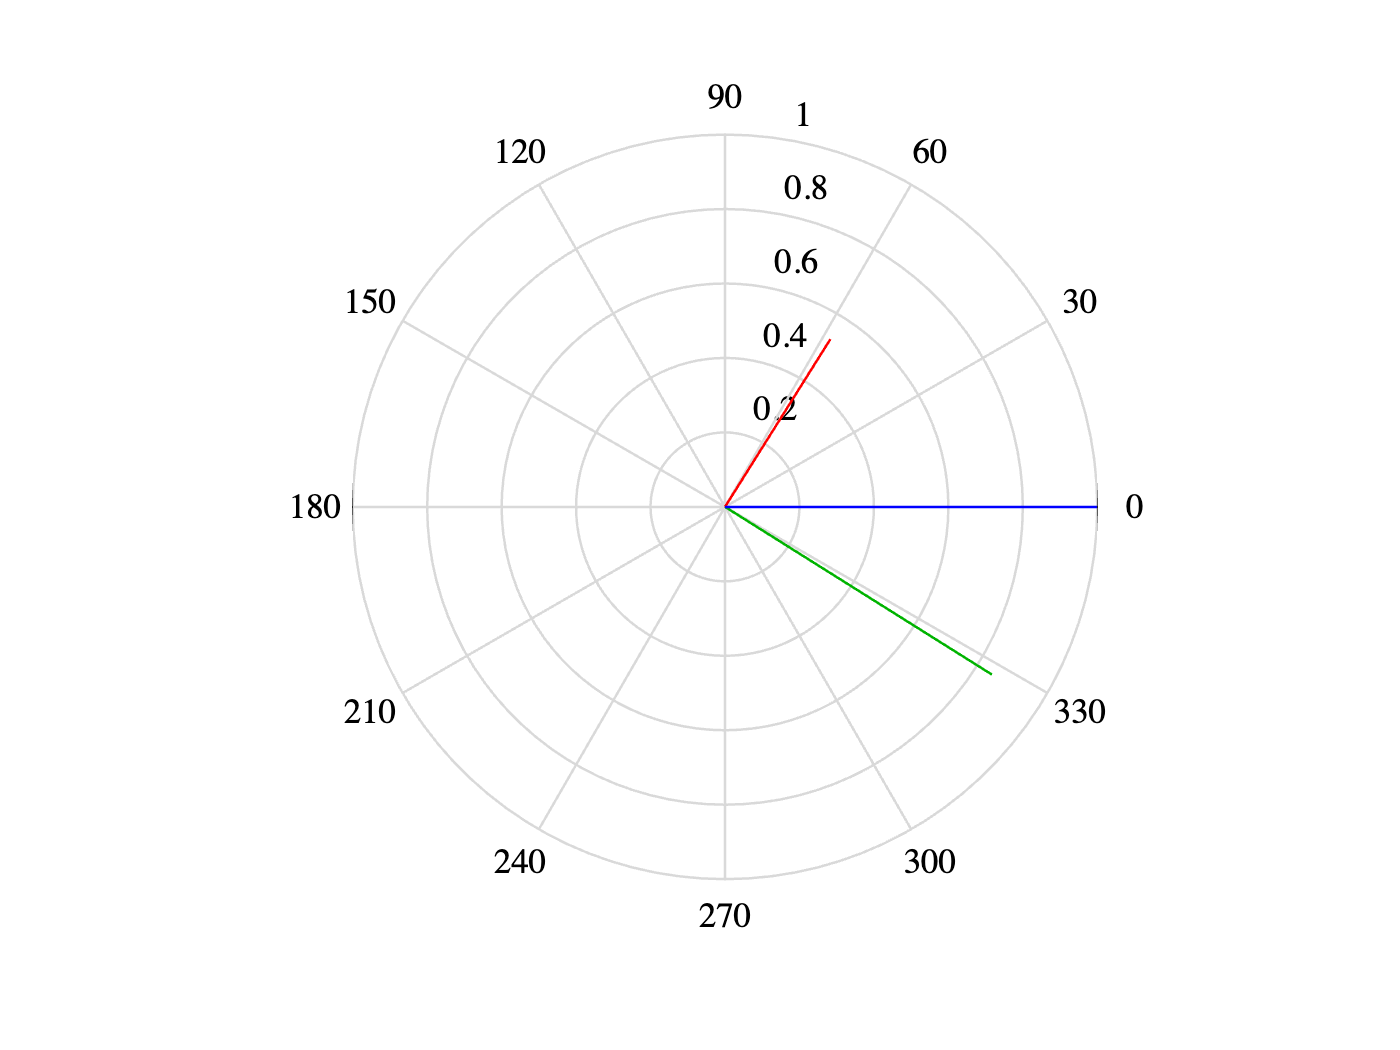

polar(angle([0 0 0; A B A+B]),abs([0 0 0; A B A+B]))

        Figure 1. Polar plot of 3 phasors, VR, VC, and their sum = $1\angle 0$. 

### When to use RMS and amplitude  

There's another practical question -- when should you *use * one or the other? \pause

Simulation maybe again the easiest way to explore some answers. Let's simulate some superposition signals and compute these metrics, and let's do it in the time domain. 

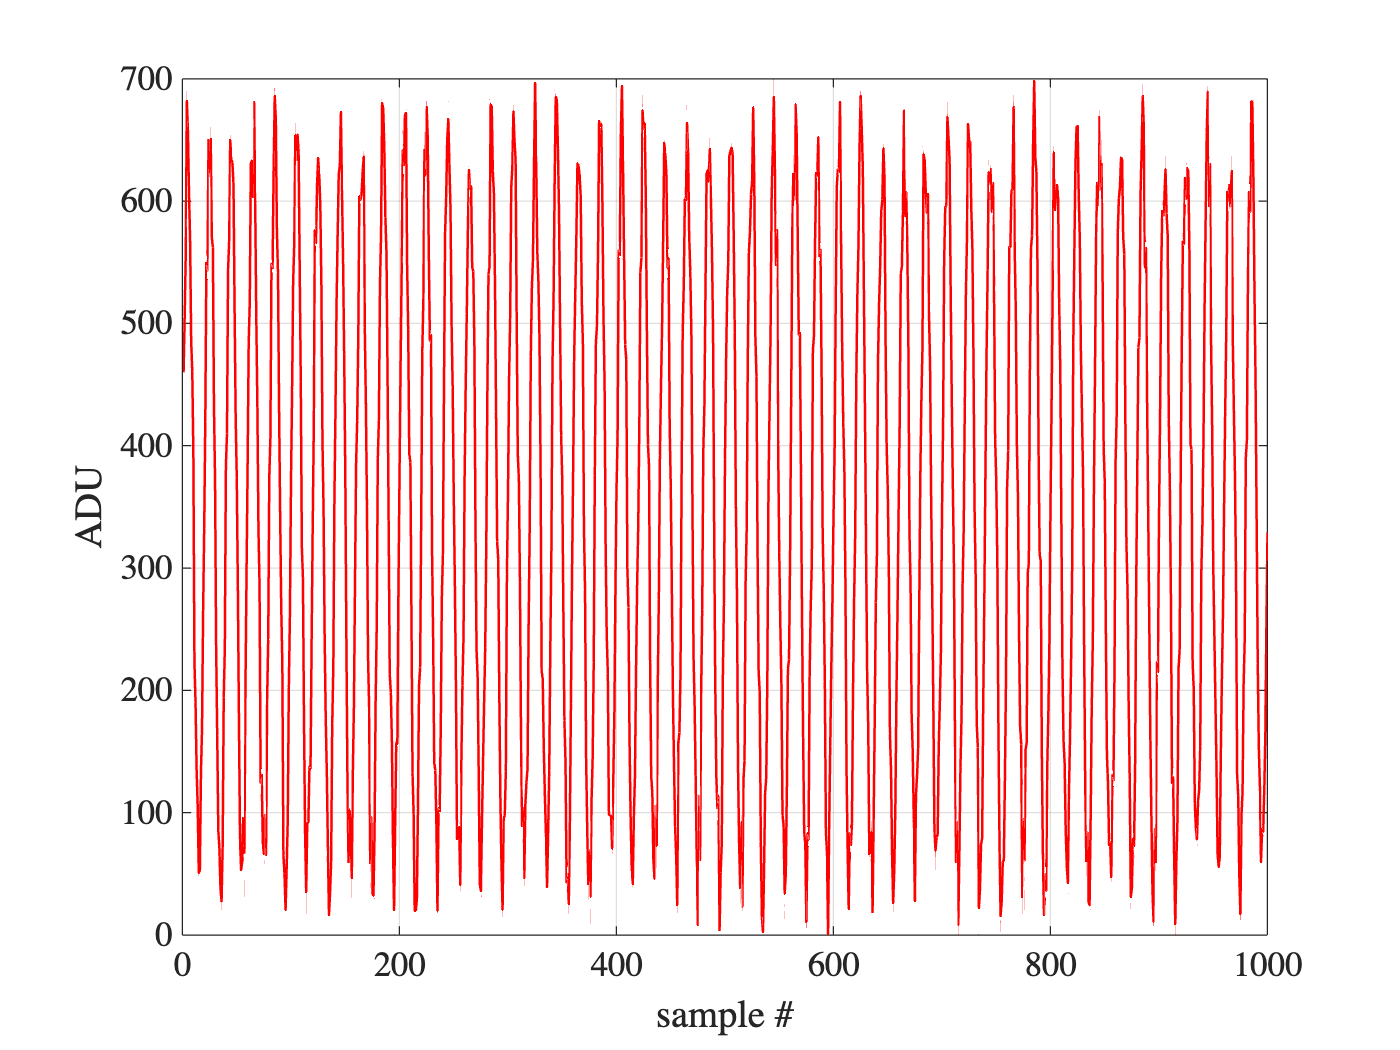

A = 300; freq = 50;
noise = 100;
t = (1:1000)'; % sample clock
data = A * (1 + sin(2*pi*freq*t/1000)) + noise * rand(size(t));
plot(data); xlabel('sample #'); ylabel('ADU'); grid;

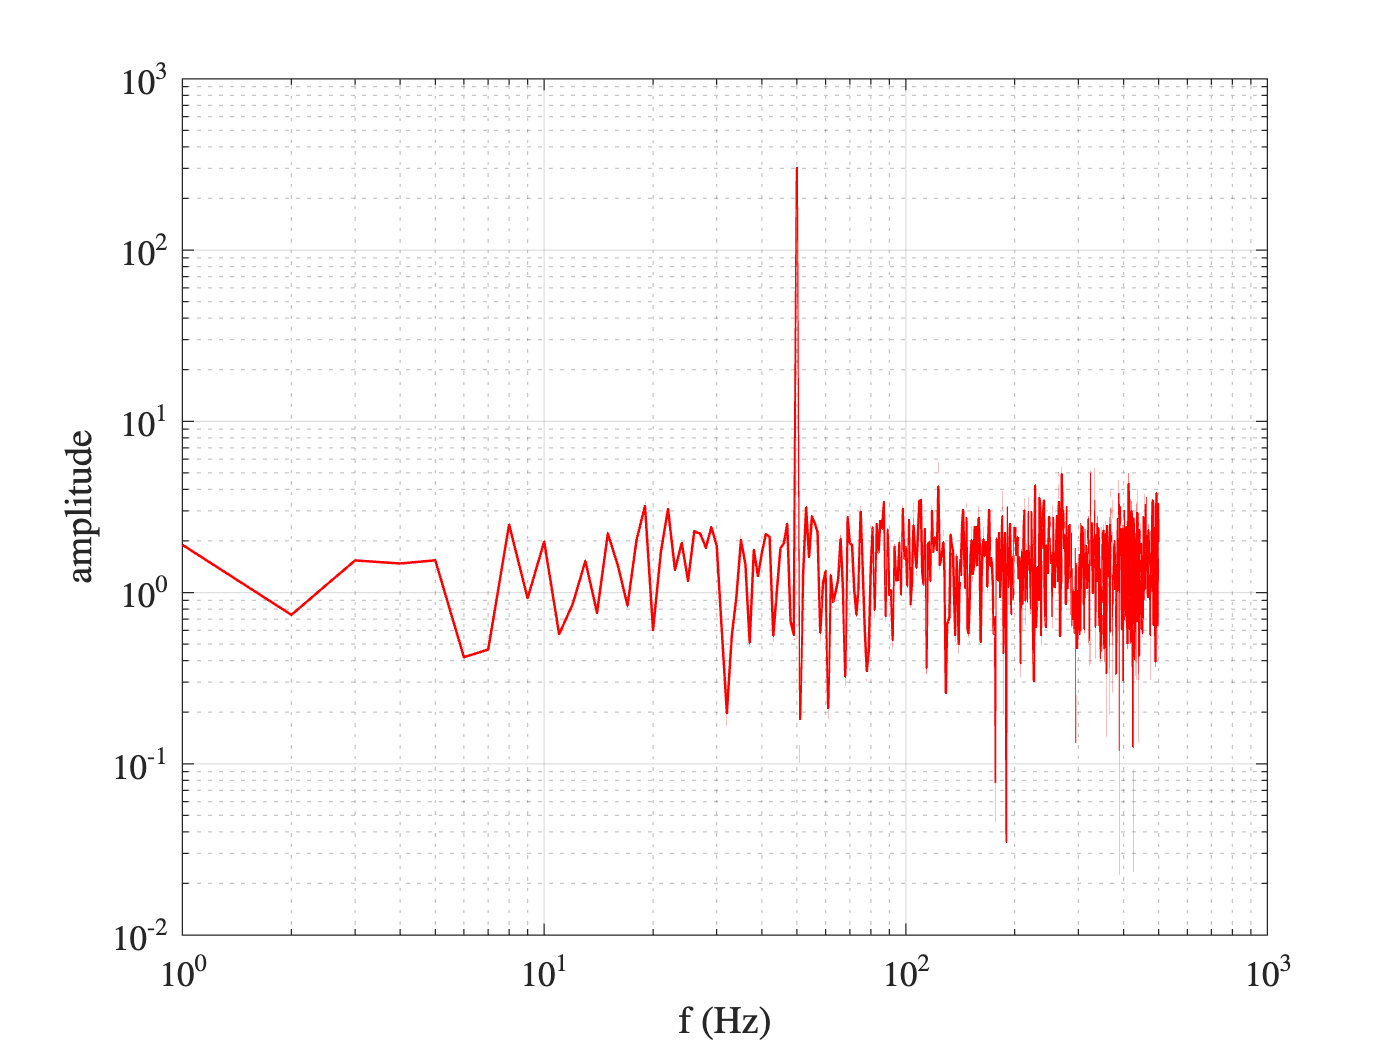

spectra = aspectrum(data,1000);

        Figure 2. data in the time and frequency domains.

The same data in the time and frequency domains of course look very different. A sinusoidal signal is spread out (almost) everywhere in time, but is highly concentrated in frequency "space". The data actually has two discrete components in the frequency domain, but aspectrum doesn't show the DC or average component: 

fdata = fft(data);
fprintf('mean(data) = %f, |f_0| = %f\n', mean(data), abs(fdata(1))/length(fdata));

mean(data) = 349.839722, |f_0| = 349.839722


Can you convince yourself where that number came from, and where it would be on the above curve? We can query the value and index of the peak with: 

[m, i] = max(spectra)

m = 299.7120

i = 50

std(data), rms(data), mrms(data), mrms(data)*sqrt(2) % other statistics

ans = 213.9470

ans = 410.0187

ans = 213.8400

ans = 302.4154

What relationships are in these numbers? 

## Digital Signal Processing

The general goal of digital signal processing is to extract a quantity from data. Often we can't directly measure the quantity we wish to, but instead measure something related to it. Imagine for example, there is a physical oscillator who's amplitude we wish to know, but all we can measure is the time series in Figure 1A, which includes the oscillation, along with a DC offset, and some random noise. We can see from how we "cooked" the data that the amplitude $A$ is estimated by both the 50th spectral amplitude and `mrms(data)*sqrt(2)`.  Run this code a few times and you'll see a pattern. Since we're just looking at one frequency, I'll call `fft` instead of `aspectrum`: 

for i=1:10
    data = A * (1 + sin(2*pi*50*t/1000)) + noise * rand(size(t));
    fdata = fft(data); 
    fprintf('%f\t%f\n', mrms(data)*sqrt(2), abs(fdata(freq+1))/length(data)*2)
end

300.273253	297.370405
302.544918	299.668487
301.290525	298.732351
303.169475	300.515948
302.917886	300.073196
302.781251	300.165549
304.305260	301.600929
301.702126	298.965700
303.835114	301.195459
306.259935	303.520128


First column is computed in the time domain with mrms, 2nd column is 

Change the fprintf to save the data: 

for i=1:10
    data = A * (1 + sin(2*pi*50*t/1000)) + noise * rand(size(t));
    fdata = fft(data); 
    measuredA(i,:) = [mrms(data)*sqrt(2), abs(fdata(freq+1))/length(data)*2];
end
mean(measuredA), std(measuredA)

ans =   302.5365  299.7470


ans =     0.7604    0.7408


I find it interesting how the standard deviations (or variance) of these two measures are very similar. But since we know the correct answer in this simulation, the relative errors are: 

fprintf('relative errors: %f rms, %f fft\n', (mean(measuredA) - A) / A)

relative errors: 0.008455 rms, -0.000843 fft


 The fft is always lower, and always much closer to the correct answer. Can you explain why? \pause Another result to appreciate is just how low the error is. Our signal has an amplitude $A$=300, and the noise has an amplitude = 100. Now those are in somewhat different units, but still, they might (erroneously) suggest a SNR ~ 3, and instead we're getting SNR ~ 1/relative error >>100. 

Why? The signal is "concentrated" in a single frequency (Fig. 2B) and it's "spread out" across all times (Fig. 2A). The random noise is spread across all frequencies and all times. The `fft` concentrates all the signal in a single point (or histogram "bin") in the frequency domain, while leaving the noise still spread out (diluted) across the frequencies. Hence the signal-to-noise ratio (SNR) is better in the frequency domain. 

In general, any transformation of the data that concentrates or focuses the signal of interest while spreading out or diluting the noise will improve SNR and be desirable. 

## When is the fft undesirable?

What happens if your data has some glitches, spikes, or extraneous values? You can guess what the next step is .... let's simulate it, and I'll reduce the uniform noise for this numerical experiment

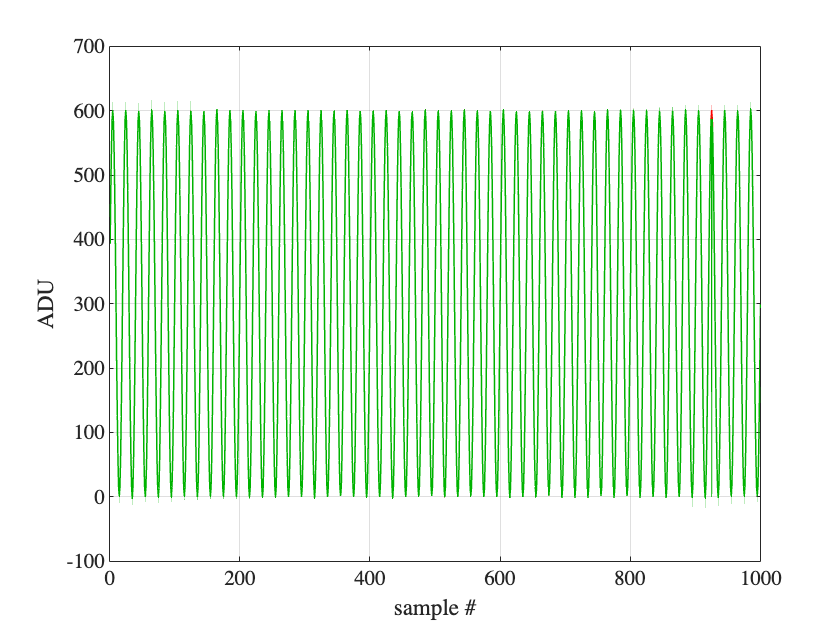

A = 300; freq = 50;
noise = 1;
t = (1:1000)'; % sample clock
data = A * (1 + sin(2*pi*freq*t/1000)) + noise * randn(size(t));
data2 = data; 
data2(randi(length(data),1)) = 0; % randomly located glitch
plot([data data2]); xlabel('sample #'); ylabel('ADU'); grid;

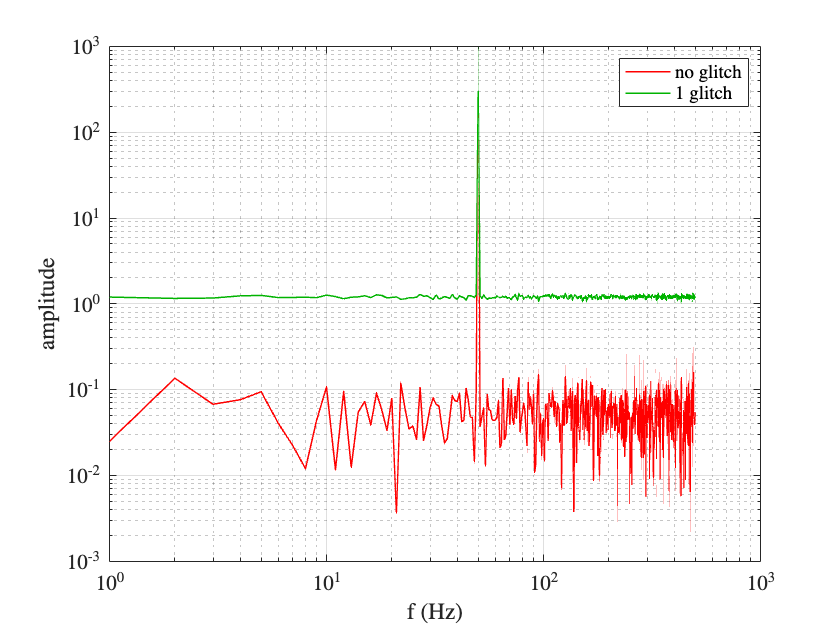

aspectrum([data data2],1e3); legend('no glitch','1 glitch')

        Figure 3. A. time domain and B spectrum of a sine wave with a random glitch.

Just one ectopic (out of place) data point (out of 1000) cost us a factor >10 in SNR! Why? Fourier transforms are hypersensitive to discontinuities. E.g., if your measurement was of a step in voltage, i.e., $V(t<t_0) = V1$ and $V(t>t_0) = V2$ and your goal is to find $V2-V1$, then the Fourier transform is likely a bad filter ("likely" because  you always should verify filters impirically).  `mean(V2)-mean(V1)` or `rms(V2)-rms(V1)` would likely give you better SNR. 

Here's another insidious form of a discontinuity in the fft: 

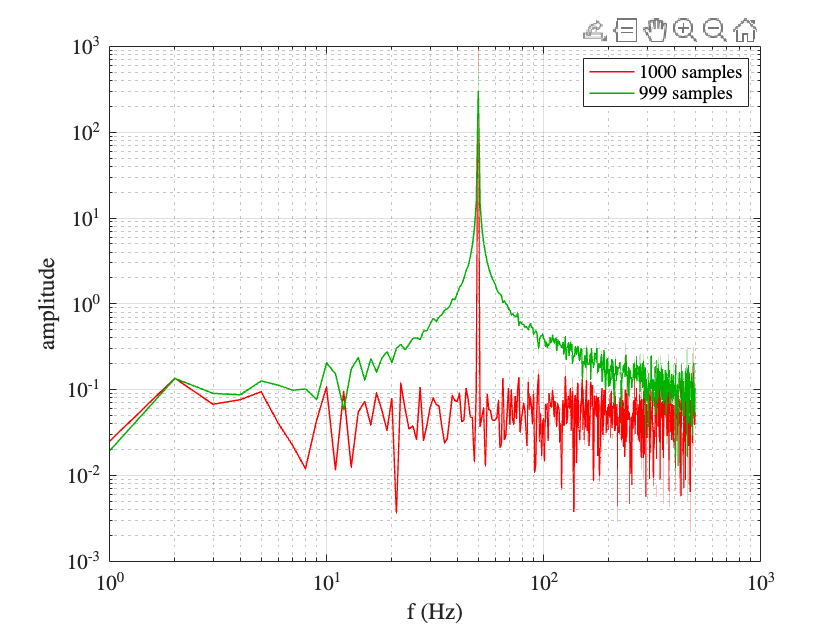

aspectrum(data,1e3);
hold on;
aspectrum(data(1:end-1),1e3); grid on;
hold off;
legend('1000 samples','999 samples'); grid on;

        Figure 4. Spectra of integral and slightly non-integral number of periods.

Again a HUGE hypersensitivity to deleting one end point out of 1000 cost several orders of magnitude of SNR near the peak! Why?? First, let me say that why is less important than what! The FFT behaves this way, it is called "ill conditioned" because of this behavior. So you've been warned! 

Why? The FFT of sine wave is a spike (called a $\delta$-function) in the frequency domain. What's the FFT of a spike, glitch, or discontinuity?

data = zeros(1000,1); data(500) = 1;
aspectrum(data, 1e3); 

        Figure 5. Spectra of a $\delta$-function or spike, $A(\omega) =$ constant!

Bet you didn't expect that! It's flat, constant amplitude across all frequencies. So the FFT turns a discontinuity or perhaps ectopic, erroneous data point that's localized in the time domain into a uniform spectrum of all frequencies -- it spreads the error *everywhere* in the frequency domain! Maybe that's helpful to your SNR, but often you're better off keeping the noise in one place than spreading it around with the FFT. 

How does Fig. 5 explain Figs 3,4? The FFT is linear, so FFT(A+B) = FFT(A)+FFT(B). We can think of the glitches or spikes as adding a B = $B_0\delta(t-t_0)$, which raises the noise floor. Lesson: make sure there are no $\delta$ functions in data that you FFT. You've been warned!! 

Let's take a conceptual leap and try to apply this. 

## Activity

**1. Measure the SNR of your function generator. **

That's a conceptual leap from what's above, so let's break it down. Your function generator puts out a signal with some amplitude, and next to that signal (in the frequency domain) is noise with some average amplitude. SNR = signal amplitude / noise amplitude. What frequency should you measure? 

How about all of them ;-). Before running the section below, explore on the command line what code solves the 2 steps in comments for a single frequency:

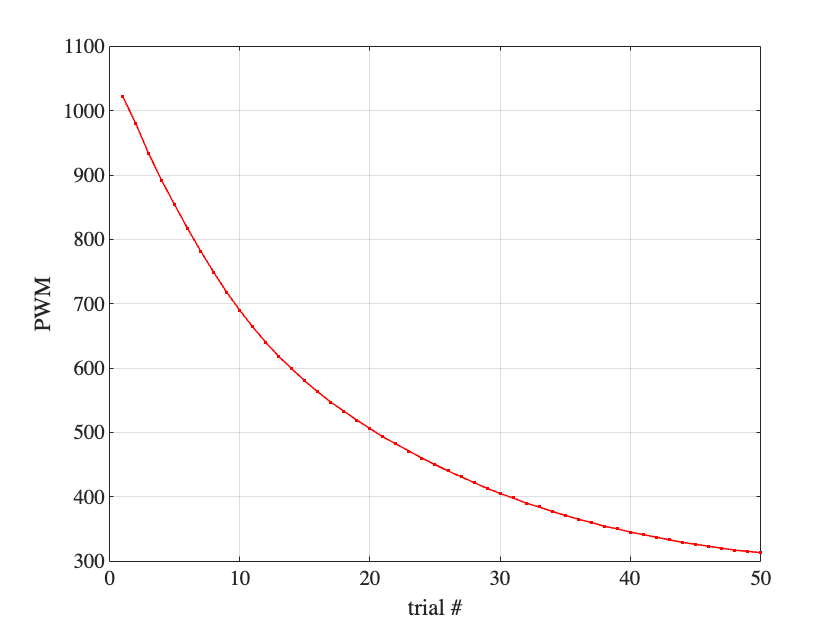

writeline(pico,'p 1023'); % and pause a long time afterwards 
writeline(pico,'d 5');
pwmVal = round(linspace(1023,300,50)'); % easy way
  freqs = logspace(log10(170),log10(8200),50)';
  pwmVal = pfreq2pwm(freqs(end:-1:1));
  plot(pwmVal,'.-'); xlabel('trial #'); ylabel('PWM'); grid;

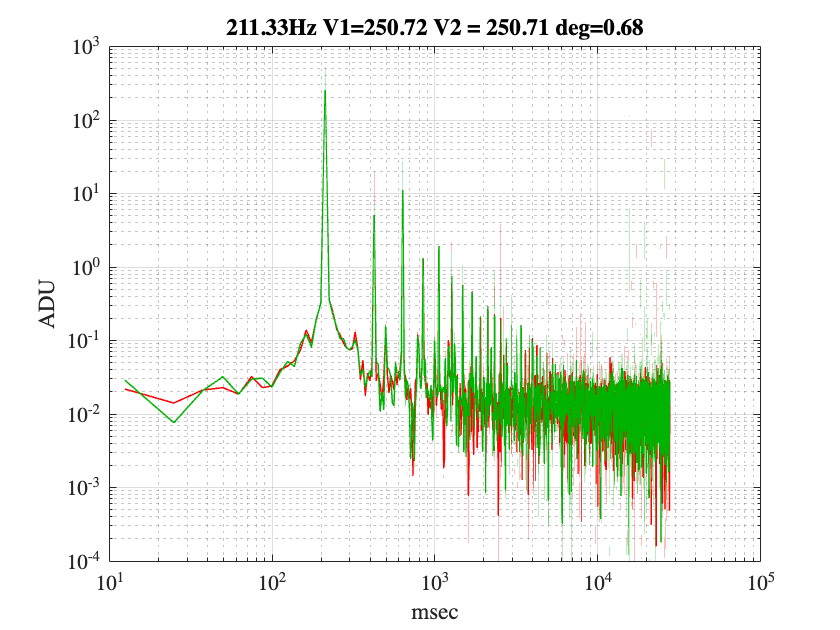

fmeas = zeros(size(pwmVal));
signalA = fmeas; noiseA = fmeas; % all zeros

for i = 1:length(pwmVal)
    writeline(pico, sprintf('p%d',pwmVal(i))); pause(.2);
    dat.runOnce = true; pscope;
    signalA(i) = abs(dat.ampl(1));% measure signal amplitude
    foo = abs(dat.fd(2:floor(length(dat.fd)/2))) / length(dat.data) * 2; % delete DC and the neg. freqs
    foo(dat.npds) = []; % delete the signal
    noiseA(i) = mean(foo); % measure average noise
    fmeas(i) = dat.freq;
end

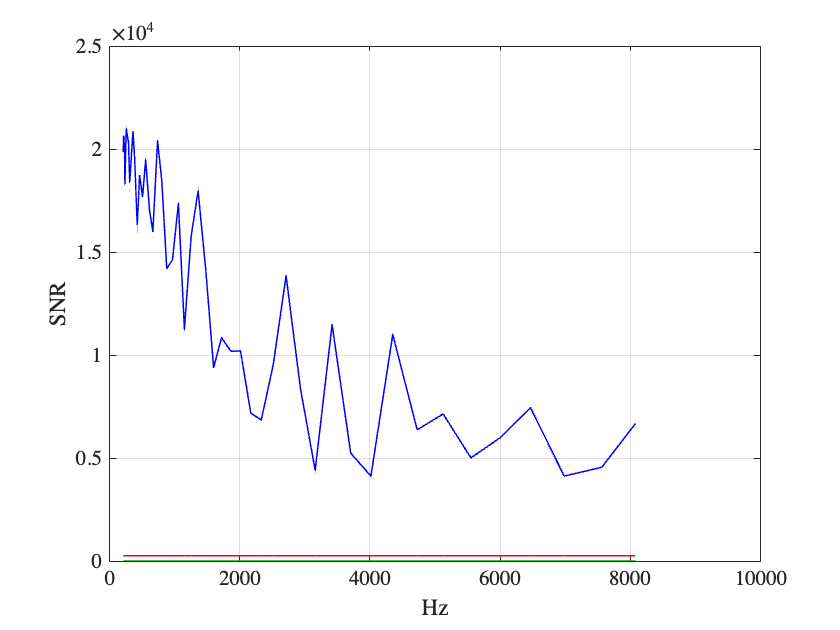

writeline(pico,'p 1023'); % we'll probably run it again
snr = signalA./noiseA;
plot(fmeas, [signalA noiseA snr]); 
xlabel('Hz'); ylabel('SNR'); grid;

**2. Measure your function generator's THD (total harmonic distortion).**

This is a common parameter of amplifiers, signal generators, etc., and is related to SNR. THD measures just the harmonics ([https://en.wikipedia.org/wiki/Total_harmonic_distortion](https://en.wikipedia.org/wiki/Total_harmonic_distortion)) -- note SNR factors generally *avoid* or exclude the harmonics (see [https://en.wikipedia.org/wiki/Total_harmonic_distortion#THD+N](https://en.wikipedia.org/wiki/Total_harmonic_distortion#THD+N)). The good news is that harmonic distortion usually falls of quickly with harmonic number, and very often only the even or the odd harmonics are significant, hence in practice the harmonic series can be approximated by just a few terms. There are examples on the above Wikipedia page for square and triangle waves that you might wish to verify (probably want a more aggressive voltage divider if you choose to connect the square wave as it may have a 12V amplitude). 

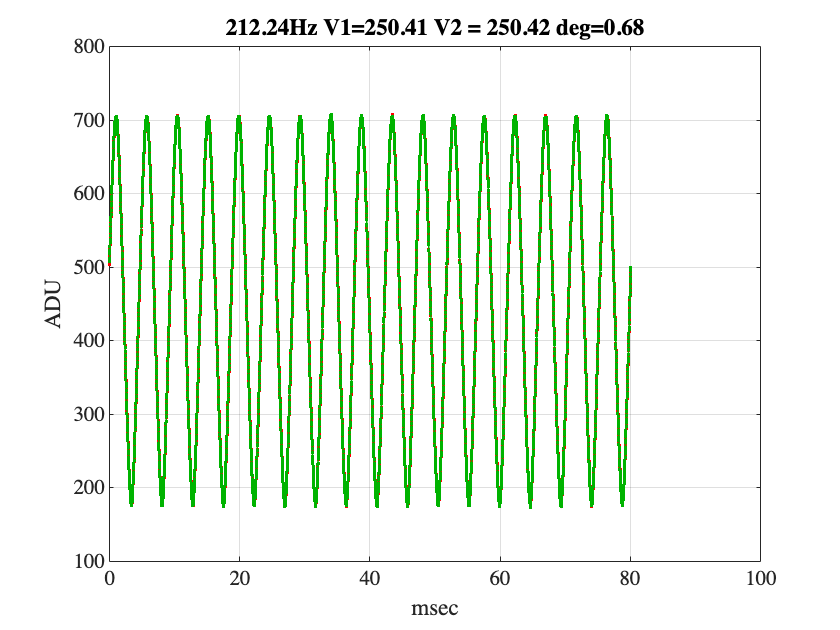

fmeas = zeros(size(pwmVal));
signalA = fmeas; noiseA = fmeas; % all zeros
for i = 1:length(pwmVal)
    writeline(pico, sprintf('p%d',pwmVal(i))); pause(.2);
    dat.runOnce = true; pscope;
    signalA(i) = abs(dat.ampl(1));% measure signal amplitude
    % for noise, want the sqrt(sum of squares of 2-5th harmonic)
    foo = abs(dat.fd(dat.npds *[2:5]+1)) / length(dat.data) * 2; % harmonics
    noiseA(i) = norm(foo); % measure average noise
    fmeas(i) = dat.freq;
end

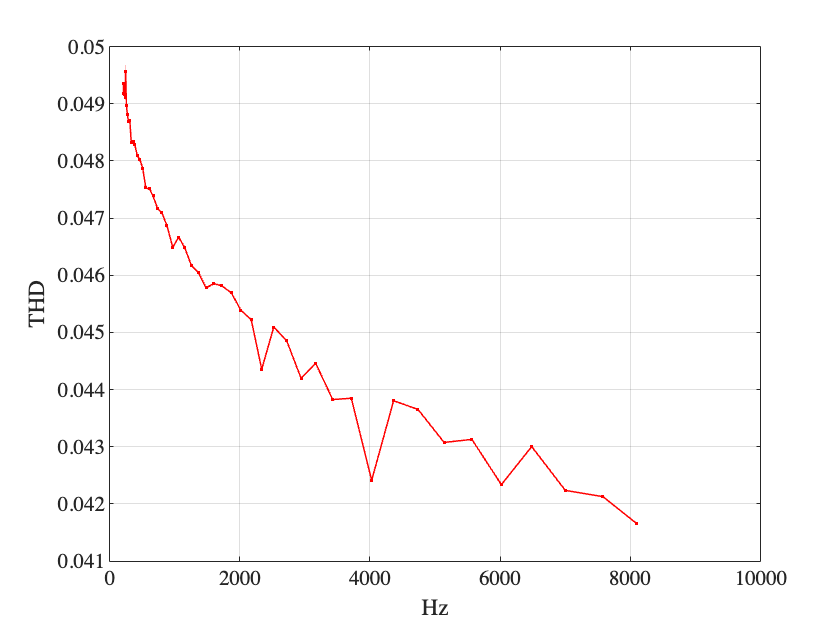

writeline(pico,'p 1023'); % we'll probably run it again
thd = noiseA ./ signalA; % total harmonic distortion
plot(fmeas, thd ,'.-'); 
xlabel('Hz'); ylabel('THD'); grid;